# Create and Customize Mesh Plots

`mesh` creates a three-dimensional surface plot that has solid edge colors and no face colors. The function plots the values in a matrix `Z` as heights above a grid in the *x*-*y* plane. The edge colors vary according to the heights specified by `Z`.

### Generate Membrane Matrix

A 2-D array is necessary for plotting a surface. To generate a known function, the membrane command can be used which returns a 2-D array of a membrane eigenfunction in a specified size.

L = 100*membrane(1,25);

### Basic Mesh Plot

Mesh plots are three-dimensional plots that look like a fish-net shaped lattice of horizontal and vertical lines that are draped over a surface. 

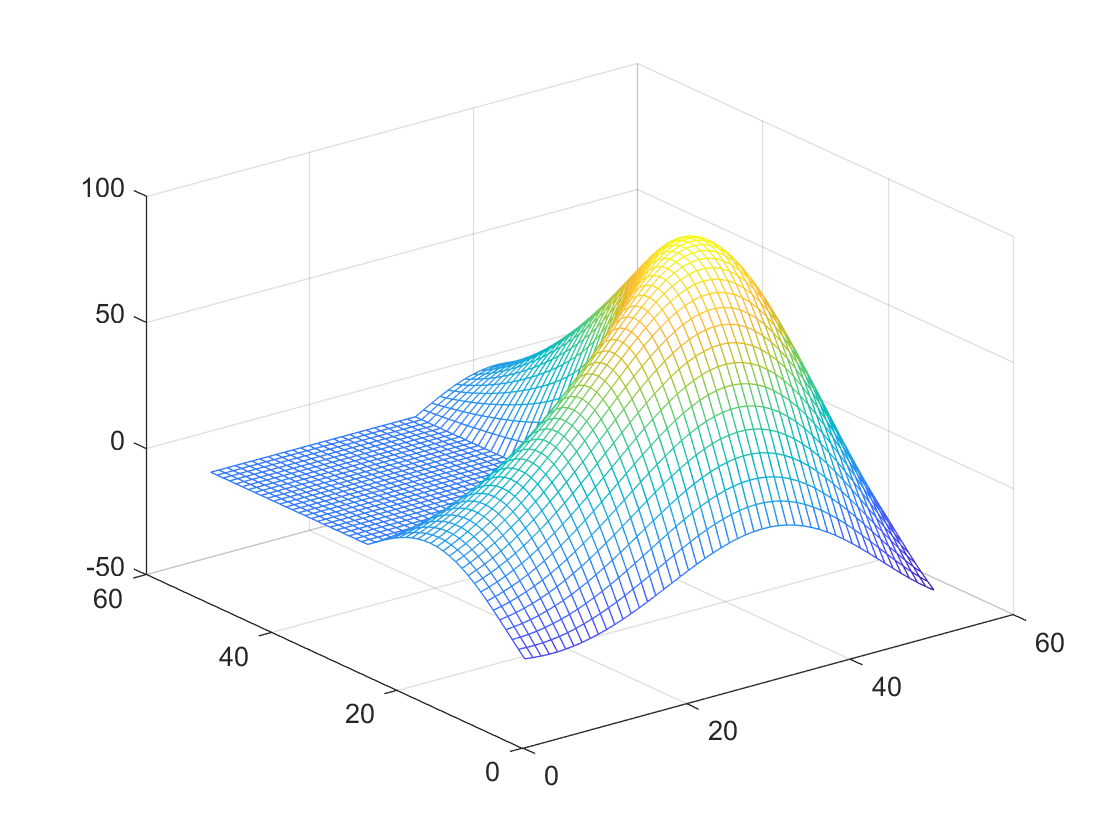

mesh(L);

## Customizing Mesh Plots

### Modify the Surface Appearance 

Create a semitransparent mesh surface by specifying the* FaceAlpha *property name-value pair with a value less than 1. Now that the surface is filled, specify the *FaceColor *property name-value pair to set the color option.

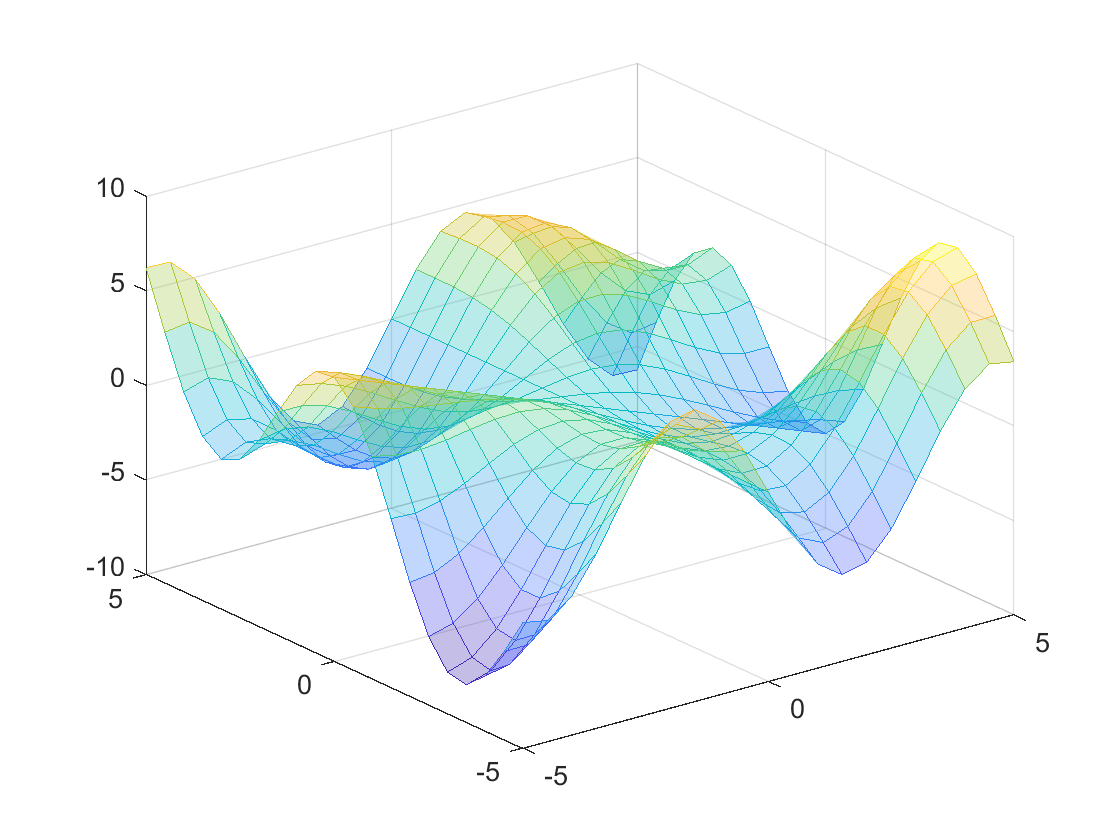

[X,Y] = meshgrid(-5:.5:5);
Z = Y.*sin(X) - X.*cos(Y);

faceColorType = "flat";
markerFaceAlpha = 0.3;
ms = mesh(X,Y,Z,...
    'FaceAlpha', markerFaceAlpha,...                % Specify the face transparency
    "FaceColor", faceColorType);                    % Specify the face coloring

### Specify the Colormap and Lighting

Customize the color pattern of the mesh plot by specifying the built-in colormap it references. A colormap scales a color gradient between the lowest and heighest $Z$ value providing improved contour and magnitude visualization. Additionally, lighting parameters are used to determine the brightess of the colormap in certain areas. The Lighting location and the lighting algorithm can be customized to offer varying appearances.

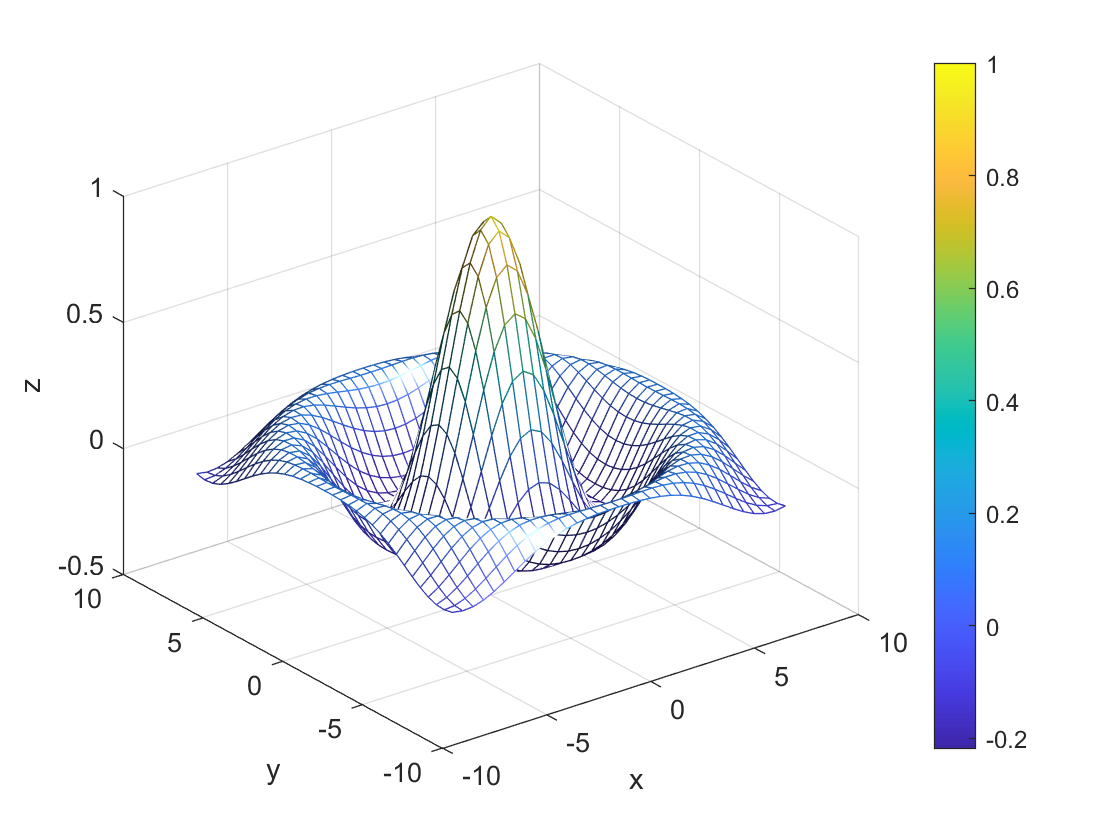

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;

mesh(X,Y,Z)
camlight
lighting gouraud;   
colormap parula;
colorbar

title("Meshed Surface Plot")
xlabel('x')
ylabel('y')
zlabel('z')

## **Additional Information**

### **Get All Mesh Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a mesh, uncomment the following code

% get(ms)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[mesh](https://www.mathworks.com/help/matlab/ref/mesh.html)